# Ingenieria Metabólica y Biologa Sintética

Alejandro Vignoni

20/01/2022

# Las ecuaciones de Volterra-Lotka

### Ecuaciones diferenciales con Matlab

Recordemos que vamos a usar el comando ode45 (o ode23s pasa sistemas stiff). Su estructura es la siguiente.

%[t,X] = ode45(@(t,x) modelo(t,x,params),tspan,x0,options);

donde

`t `es la variable independiente

`x `es la variable (o vector de variables) dependientes 

`modelo` es el nombre de la función que da la ecuación diferencial,

`params` contiene valores de parámetros

`tspan` indica el tiempo durante el cual se quiere obtener la solución,

`x0` representa las condiciones iniciales,

`options` las opciones del algoritmo integrador.

### Volterra-Lotka 

Recordemos que las ecuaciones vienen dadas por esta expresión:


$$\frac{dx(t)}{dt}=\alpha x(t) - \beta x(t) y(t) \\
\frac{dy(t)}{dt}=\delta x(t) y(t) - \gamma y(t)$$


Ir al final de este documeto para ver la definición de la funcion.

El modelo de Lotka-Volterra representa las interacciones de dos poblaciones, donde una son las presas (que denotaremos por x) y la otra son la población de depredadores (que denotaremos por y).

**Programa principal**

Primero debemos definir el vector de tiempo: para ello discretizamos el intervalo de tiempo con el fin de hallar las soluciones numéricas de esta ecuación para una condición inicial particular que nos será facilitada. Vamos a discretizar el intervalo [0,20], con un paso de 0.2.

%Tiempo (seg)
tfin=8; dt=0.01;
tspan = 0:dt:tfin;

Definimos los parámetros que en este caso vamos a pasarle a la función. Y los guardamos en el vector `params.` Hay que tener en cuenta el orden en el que guardamos los parámetros en el vector `params, `tiene que ser el mismo con el que se recuperan dentro de la función (al final del documento).

% Parámetros:
a = 5;
b = 2;
d = 3;
g = 6;
params=[a,b,d,g];

y las condiciones iniciales

% Condiciones iniciales
x0=[4 1];

% Tolerancias ode45
options=odeset('RelTol',1e-6,'Stats','off');

Finalmente, resolvemos la ecuación (simulamos) con el comando ode. 

%Llamada solver ode45
[t,X] = ode23s(@(t,x) modelo_VL(t,x,params),tspan,x0,options);
prey = X(:,1);
pred = X(:,2);

Finalmente, representamos gráficamente la solución.

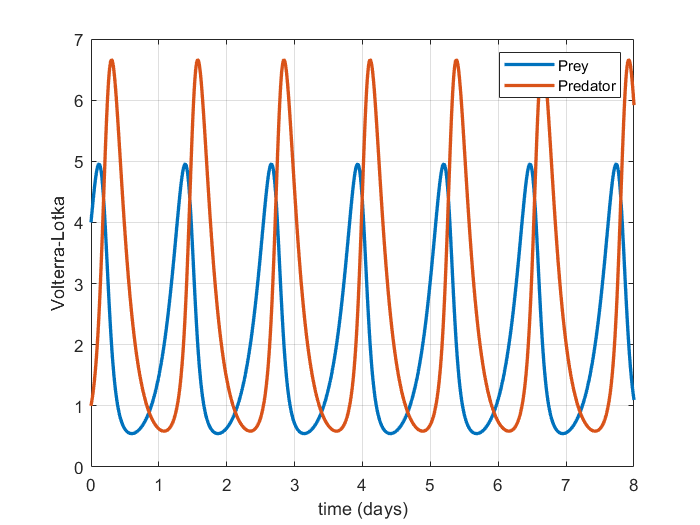

%Graficar respuesta modelo
figure;
plot(t,X,'LineWidth',2); grid on;
xlabel('time (days)'); ylabel('Volterra-Lotka');
legend('Prey','Predator')

Ahora vamos a calcular las derivadas x' y y' para distintos valores de x e y para poder contruir el campo de velocidades en el retrato de fase. Para ello deminimos el rango para el que queremos calcular el campo de velocidades y armamos una grilla con el comando `meshgrid,` a partir de los dos vectores de x e y.

x_vector = 0:1:6;
y_vector = 0:1:6;
[xm,ym] = meshgrid(x_vector,y_vector);

Luego guardamos (preallocate) el lugar en memoria para calcular las devivadas luego:

u = zeros(size(xm));
v = zeros(size(xm));

Ahora utilizaremos utilizar un único bucle sobre cada elemento para calcular las derivadas en cada punto de la grilla (xm, ym):

for i = 1:numel(xm)
    Yprime = modelo_VL(t,[xm(i); ym(i)],params);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end

Entonces para cada conjunto de valores de x e y, tenemos los valores de sus derivadas u, y v.

Ahora podemos calcular tistintas trayectorias, partiendo de distintas condiciones iniciales para dibujarlas sobre el retrato de fase. Calculamos y dibujamos las trayectorias en el plano fase:

figure;
plot(X(:,1),X(:,2),'LineWidth',2); grid on;
hold on
xlabel('Prey'); ylabel('Predator');
title('Phase portrait')
[t,X] = ode23(@(t,x) modelo_VL(t,x,params),tspan,[2 4.5],options);
prey = [prey X(:,1)];
pred = [pred X(:,2)];
plot(X(:,1),X(:,2),'LineWidth',2);

[t,X] = ode23(@(t,x) modelo_VL(t,x,params),tspan,[2 5.5],options);
prey = [prey X(:,1)];
pred = [pred X(:,2)];
plot(X(:,1),X(:,2),'LineWidth',2);

[t,X] = ode23(@(t,x) modelo_VL(t,x,params),tspan,[2 2.5],options);
prey = [prey X(:,1)];
pred = [pred X(:,2)];
plot(X(:,1),X(:,2),'LineWidth',2);


y dibujamos el campo de velocidades con el comando `quiver`

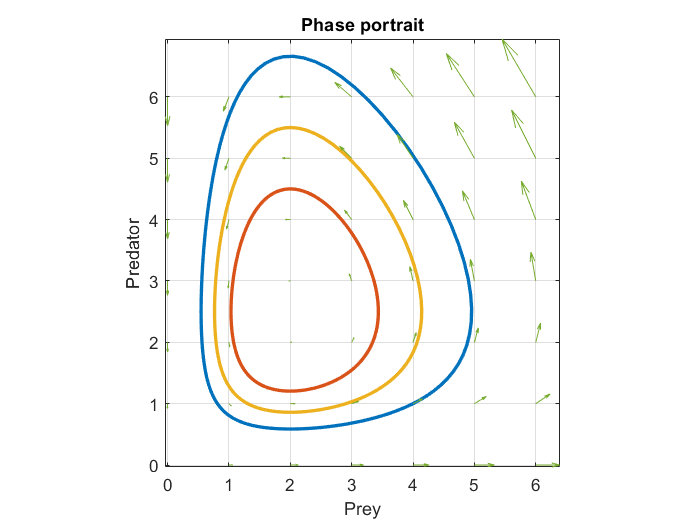

quiver(xm,ym,2*u,2*v); 
axis tight equal;

Ademas vamos a dibujars las presas y predadores para las distintas condiciones iniciales

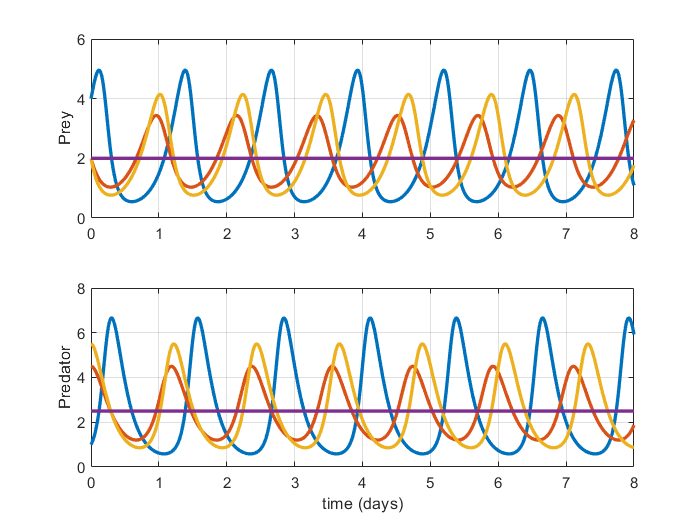


figure
subplot(211)
plot(t,prey,'LineWidth',2); grid on;
ylabel('Prey');
subplot(212)
plot(t,pred,'LineWidth',2); grid on;
ylabel('Predator');
xlabel('time (days)');

#### Definicion del modelo/ecuación ODE como una función

Definimos ahora una función que nos de el término derecho de las ecuaciones. Ésta expresión será evaluada en un instante $t$ y tomando un valor $x$, con los parámetros dados `parameters`. Esta función nos sirve para tratar algunas cuestiones a la hora de definir funciones. Como podéis ver a esta función se le pasa:

* El valor $t$ en el que es evaluada,

* el valor de $x$ donde es evaluado x

* los parámetros que nos permiten definir la ecuación

**Modelo ODE**

function [dx_dt]= modelo_VL(t,x,params)
% Model parameters:
a= params(1);
b= params(2);
d= params(3);
g= params(4);

dx1 =  a .* x(1)          - b .* x(1) .* x(2) ;
dx2 =  d .* x(1)  .* x(2) - g .* x(2) ;

dx_dt = [dx1; dx2];

end